**%Week7_lec**

**Task 1- Background subtraction**

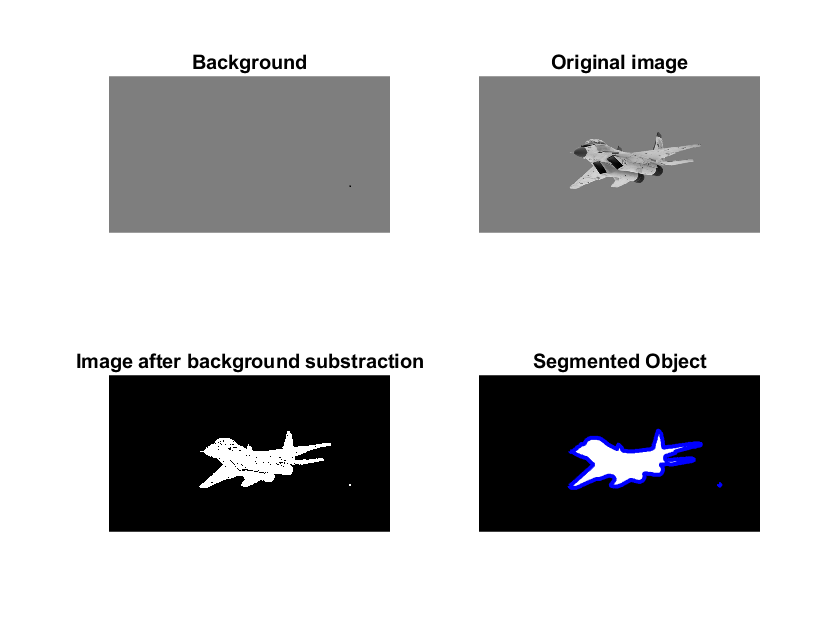

I1 = imread ('im_1.png'); I1 = rgb2gray(I1); I1_d = double(I1);
figure, subplot(2,2,1), imshow(I1), title ("Background");
I2 = imread ('im_2.png'); I2 = rgb2gray(I2); I2_d = double(I2);
subplot(2,2,2), imshow(I2), title ("Original image");
g = abs(I1_d - I2_d) > 5; %get abstract value
subplot(2,2,3), imshow(g), title("Image after background substraction");
g1 = imfill(g, 'holes'); % remove holes
subplot(2,2,4), imshow(g1), title("Segmented Object"); hold on;
[B,L] = bwboundaries(g1); % mark the boundary
for k = 1:length(B)
boundary = B{k};
plot(boundary(:,2), boundary(:,1), 'b', 'LineWidth', 2)
end

**Task 2- Global Thresholding **

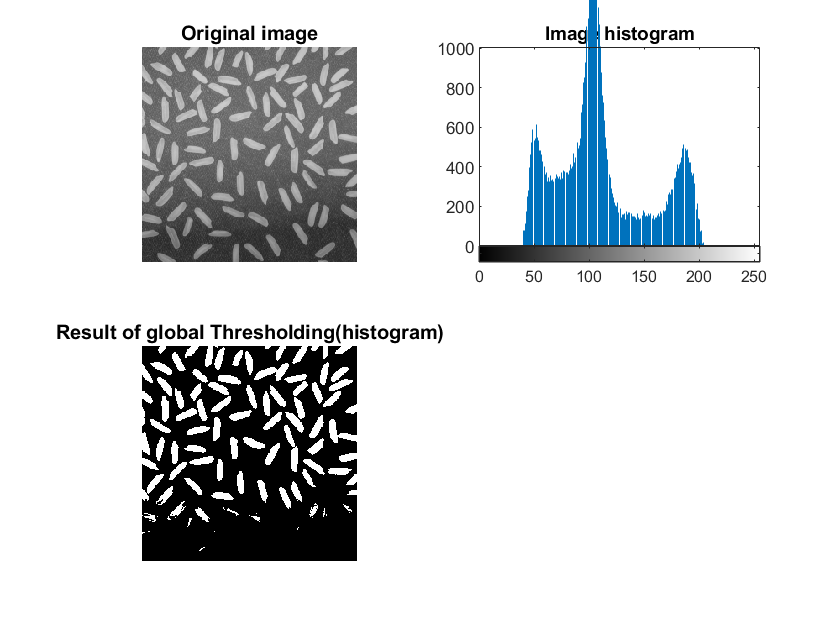

I = imread('rice.png');
figure, subplot (2,2,1),imshow(I), title ("Original image");
subplot (2,2,2),imhist(I), title("Image histogram");
T = 150;
BW = imbinarize(I, T/255);
subplot (2,2,3),imshow(BW), title("Result of global Thresholding(histogram)");

**Task 3- Adaptive/Local thresholding using the mean and standard deviation as the thresholding criterion.**

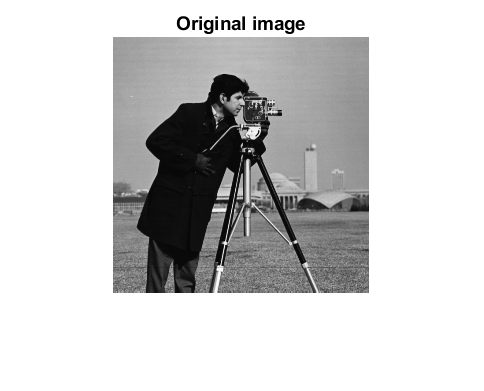

I = imread('cameraman.tif');
I = double(I);
figure, imshow(uint8(I)), title ("Original image");

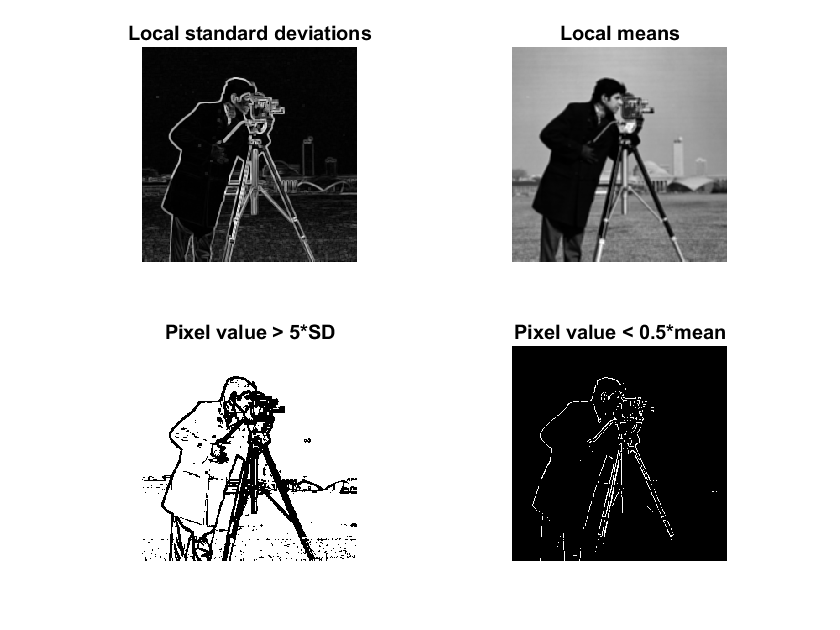

nhood = ones(3);
SIG = stdfilt(I,nhood); % compute local standard deviation
figure, subplot(2,2,1),imshow(SIG,[]), title ("Local standard deviations");
mean_filter = nhood/9; % compute local mean
MEAN = imfilter(I,mean_filter,'replicate');
subplot(2,2,2),imshow(MEAN, [] ), title ("Local means");
g1 = (I>5*SIG);
subplot(2,2,3),imshow(g1), title ("Pixel value > 5*SD");
g2 = (I<0.5*MEAN);
subplot(2,2,4),imshow(g2), title ("Pixel value < 0.5*mean");

**Task 4- Adaptive thresholding using adaptthresh**

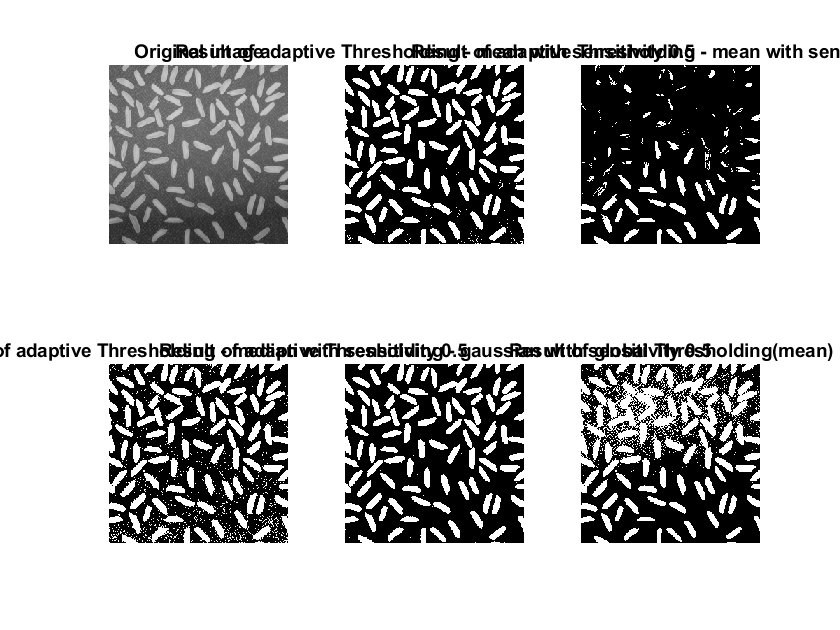

I = imread('rice.png');
figure, subplot (2,3,1),imshow(I), title ("Original image");
T = adaptthresh(I);
% The threshold is normalized to the range [0, 1].
% 2*floor(size(I)/16)+1 (default)
BW = imbinarize(I,T);
subplot (2,3,2),imshow(BW), title("Result of adaptive Thresholding - mean with sensitivity 0.5");
%sensitivity is a scalar in the range [0,1] that indicates sensitivity towards
%thresholding more pixels as foreground.
T = adaptthresh(I, 0.1); % The threshold is normalized to the range [0, 1].
BW = imbinarize(I,T);
subplot (2,3,3),imshow(BW), title('Result of adaptive Thresholding - mean with sensitivity 0.1');

T = adaptthresh(I, 'Statistic', 'median');
% The threshold is normalized to the range [0, 1].
BW = imbinarize(I,T);
subplot (2,3,4),imshow(BW), title("Result of adaptive Thresholding - median with sensitivity 0.5");
T = adaptthresh(I, 'Statistic','gaussian');
% The threshold is normalized to the range [0, 1].
BW = imbinarize(I,T);
subplot (2,3,5),imshow(BW), title("Result of adaptive Thresholding - gaussian with sensitivity 0.5");
T = mean2(I);
BW = imbinarize(I,T/255);
subplot(2,3,6), imshow(BW), title("Result of global Thresholding(mean)");

%This part is included to examine the different forms of adaptthresh function
%against the global thresholding result

**Task 5- Iterative Thesholding**

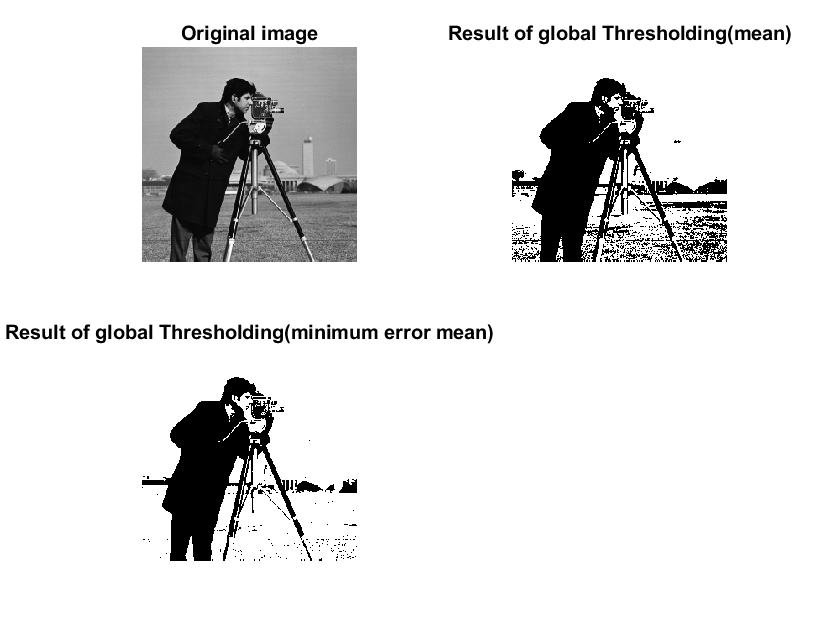

I = imread('cameraman.tif'); figure, subplot(2,2,1), imshow(I), title ("Original image");
T = mean2(I);
BW1 = imbinarize(I,T/255);
subplot(2,2,2), imshow(BW1), title("Result of global Thresholding(mean)");
% minimum error mean intensity
done = false;
while (~done)
    g = I > T;
    T_next = 0.5 *(mean2(I(g)) + mean2(I(~g)));
    done = abs(T - T_next) < 0.5;
    T = T_next;
end
BW2 = imbinarize(I,T/255);
subplot(2,2,3), imshow(BW2), title("Result of global Thresholding(minimum error mean)");

**Task 6- Otsu's Thresholding**

I = imread('cameraman.tif');
figure, subplot(1,2,1), imshow(I), title ("Original image");
% Otsu's threshold
level = graythresh(I) % The threshold is normalized to the range [0, 1].

level = 0.3451

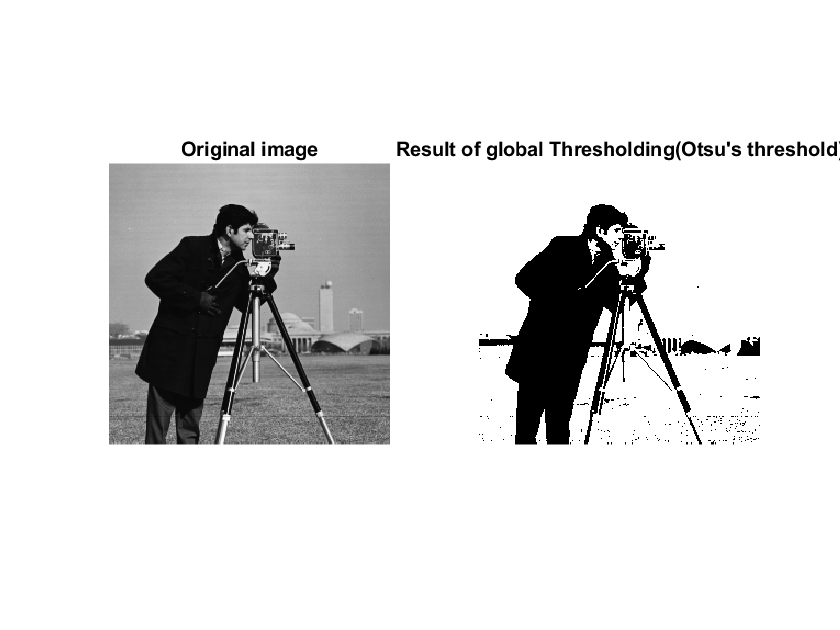

BW3 = imbinarize(I,level);
subplot(1,2,2), imshow(BW3), title("Result of global Thresholding(Otsu's threshold)");

**Task 7-K-means clustering algorithm**

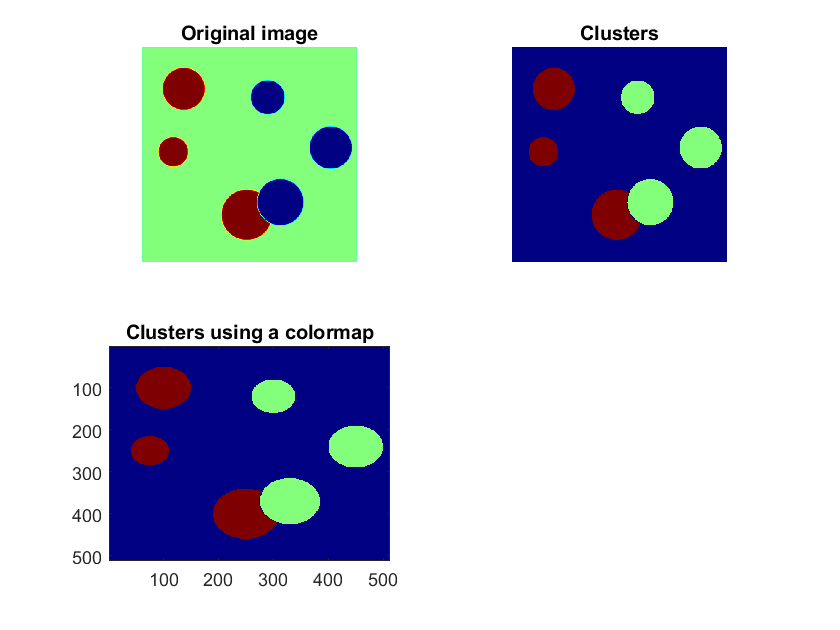

% % % % % gray image
I = double(imread('circlesBrightDark.png'));
figure,subplot(2,2,1), imshow(I,[]), title ("Original image");
nClasses = 3;
indexes = kmeans(I(:),nClasses); %kmeans uses the squared Euclidean distance metric
class_image = reshape(indexes,size(I));
subplot(2,2,2),imshow(class_image,[]), title ("Clusters");
subplot(2,2,3),imagesc(class_image), title ("Clusters using a colormap");
colormap(jet);

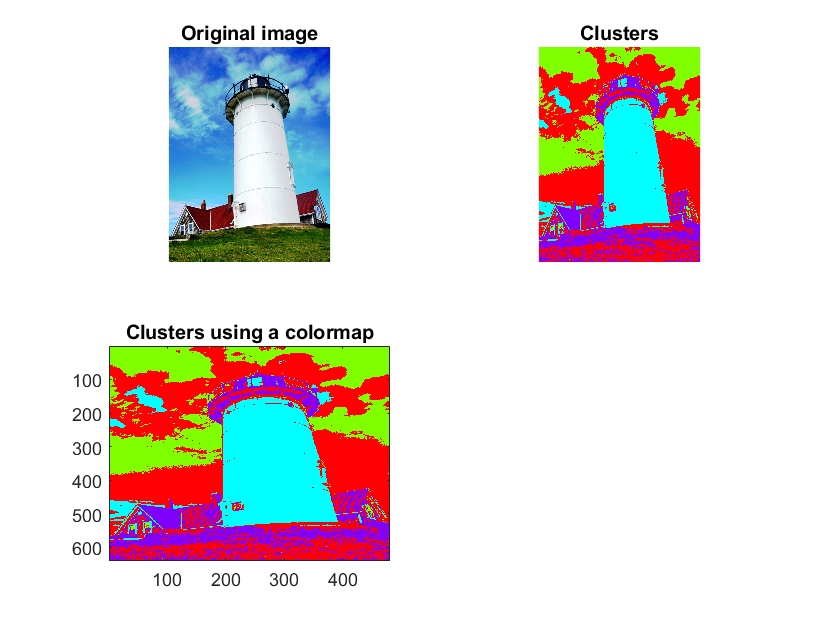

% % % % % color image
I = imread('lighthouse.png');
figure,subplot(2,2,1),imshow(I,[]), title ("Original image");
flatImg = double(reshape(I,size(I,1)*size(I,2),size(I,3)));
nClasses = 5;
indexes = kmeans(flatImg,nClasses);
img = reshape(indexes,size(I,1),size(I,2));
subplot(2,2,2),imshow(img,[]), title ("Clusters");
subplot(2,2,3),imagesc(img), title ("Clusters using a colormap");
colormap(hsv);

**Task 8-The split-and-merge segmentation**

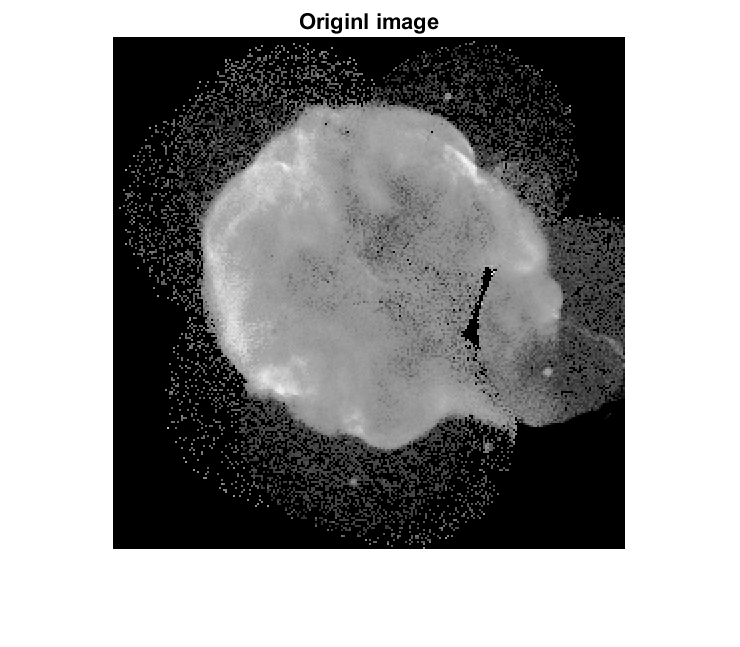


I = imread('split_merge.tif'); figure, imshow(I), title ("Originl image");

Q = 2^nextpow2(max(size(I))); %Exponent of next higher power of 2
[m,n] = size(I)

m = 512

n = 512

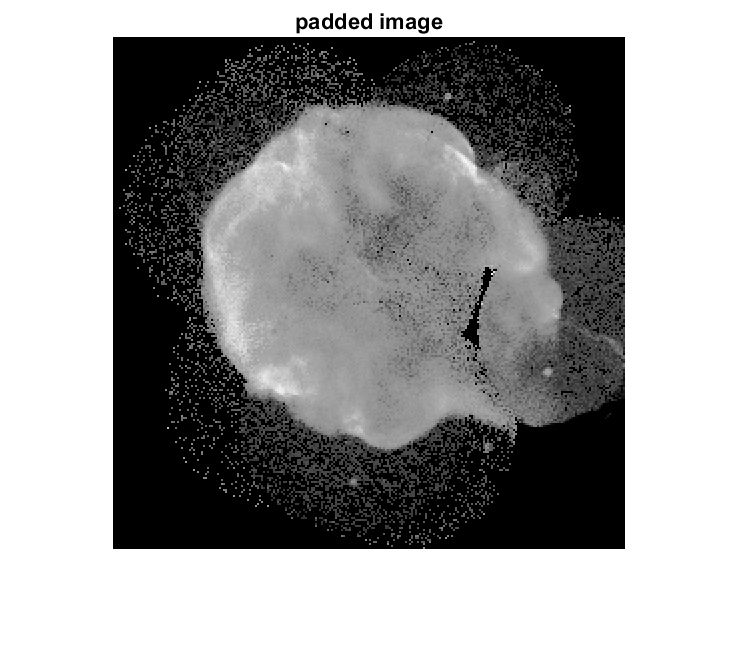

% pads array A with 0s (zeros). padsize is a vector of nonnegative integers that specifies both
%the amount of padding to add and the dimension along which to add it.
I = padarray(I, [Q-m, Q-n], 'post'); %Pad after the last array element along each dimension.
figure, imshow(I), title ("padded image");

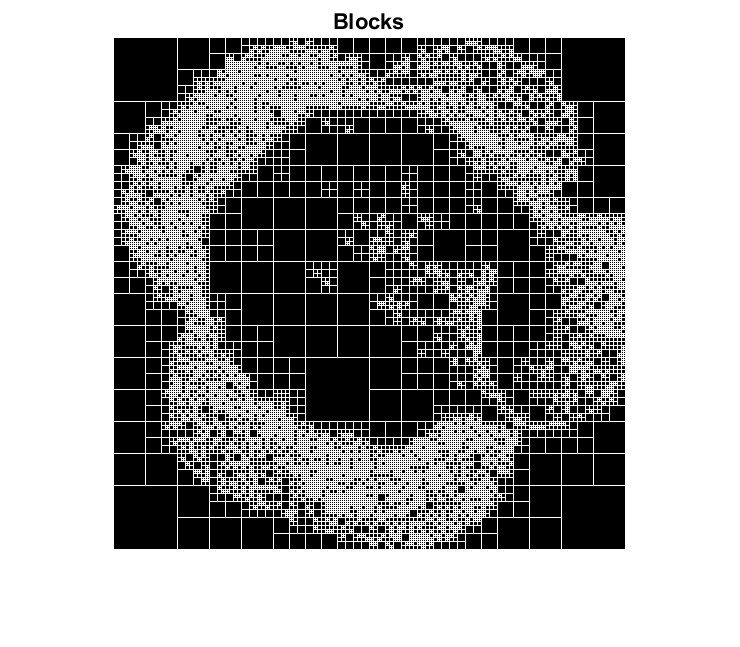

S = qtdecomp(I, .25, 1); %Quadtree decomposition, qtdecomp splits a block unless all
%elements in the block are equal.
% sparse matrix. If S(k,m) is nonzero, then (k,m) is the upper left corner of a block in the
%decomposition, and the size of the block is given by S(k,m).
blocks = repmat(uint8(0),size(S));
% Repeat copies of array, Create a matrix with size S with zeroes
for dim = [512 256 128 64 32 16 8 4 2 1]
    numblocks = length(find(S==dim)); %find the number of blocks for each size
    if (numblocks > 0)
        values = repmat(uint8(1),[dim dim numblocks]);
        %Create a matrix to hold new values for each block, all ones
        values(2:dim,2:dim,:) = 0; % put zeroes as middles values
        blocks = qtsetblk(blocks,S,dim,values); %Set block values in quadtree decomposition
    end
end
figure,imshow(blocks,[]), title ("Blocks");



% % % % % merging
Lmax = full(max(S(:))); %take the maximum block size
disp (Lmax);

    64



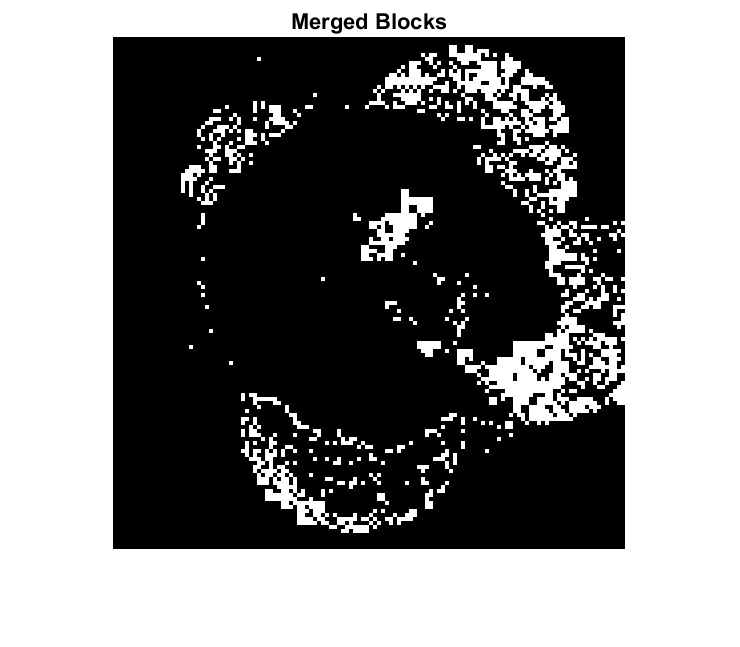

g = zeros(size(I)); % matrices for the output
marker = zeros(size(I));
for K = 1:Lmax
    [vals, r, c] = qtgetblk(I,S,K); % take the values for all same size blocks
    if ~isempty(vals)
        for L = 1:length(r) %for all the blocks
            xlow = r(L); % row and clolumn values for upper left coner
            ylow = c(L);
            xhigh = xlow + K - 1; % row and clolumn values for down right coner
            yhigh = ylow + K - 1;
            region = I(xlow:xhigh,ylow:yhigh); % take the intensity values for all the blocks
            flag = predicate(region); % check whether the block intensities satisfy the condition for
            %merging
            if flag % if satisfies
                g(xlow:xhigh,ylow:yhigh) = 1; % mark the region as forground
                marker (xlow,ylow) = 1; % mark all upper left corners
            end
        end
    end
end


figure, imshow(g,[]), title ("Merged Blocks");

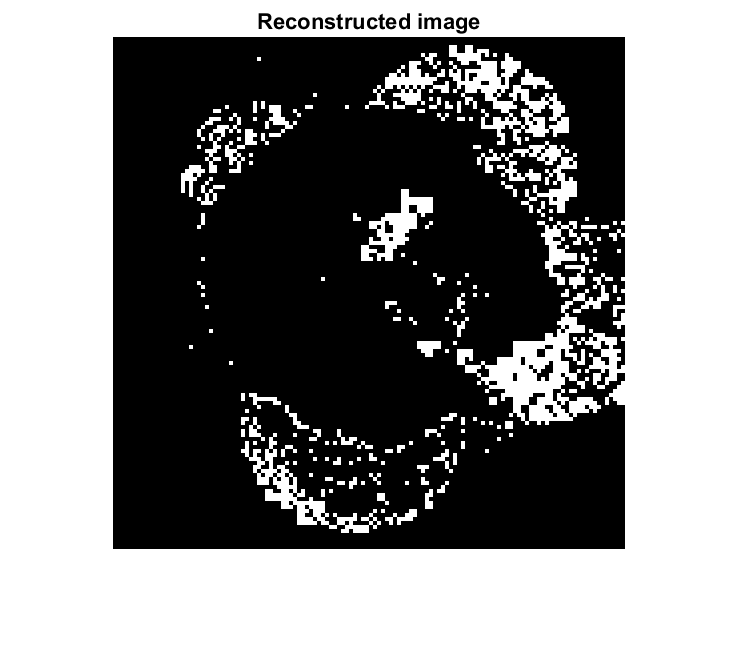

g1 = imreconstruct(marker, g); %Morphological reconstruction
figure, imshow(g1,[]), title ("Reconstructed image");

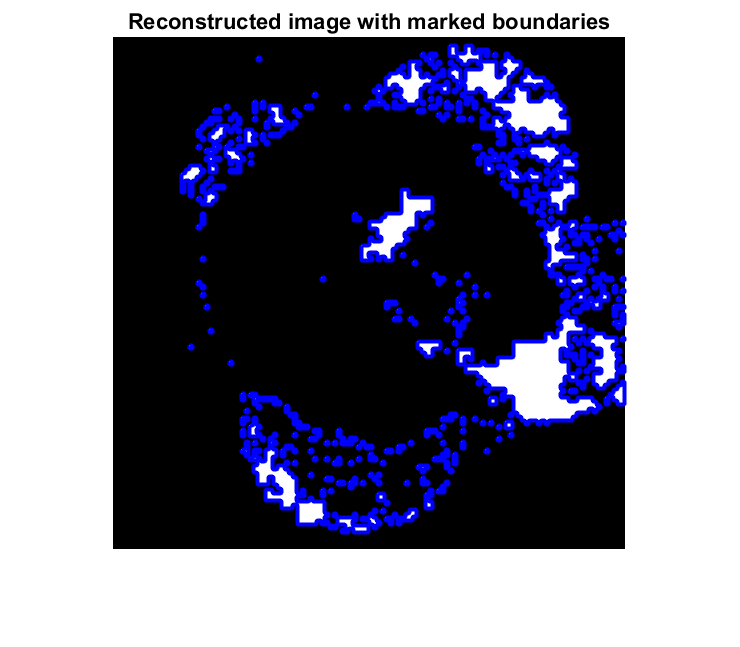

g2 = imfill(g1, 'holes'); % Fill the holes in the foreground
figure, imshow(g2), title ("Reconstructed image with marked boundaries"); hold on;
[B,L] = bwboundaries(g2); % identify the boundaries of foreground
for k = 1:length(B)
    boundary = B{k};
    plot(boundary(:,2), boundary(:,1), 'b', 'LineWidth', 2)
end

%% Function to check whether the block intensities satisfy the condition for merging

**Task 9-Watershed**

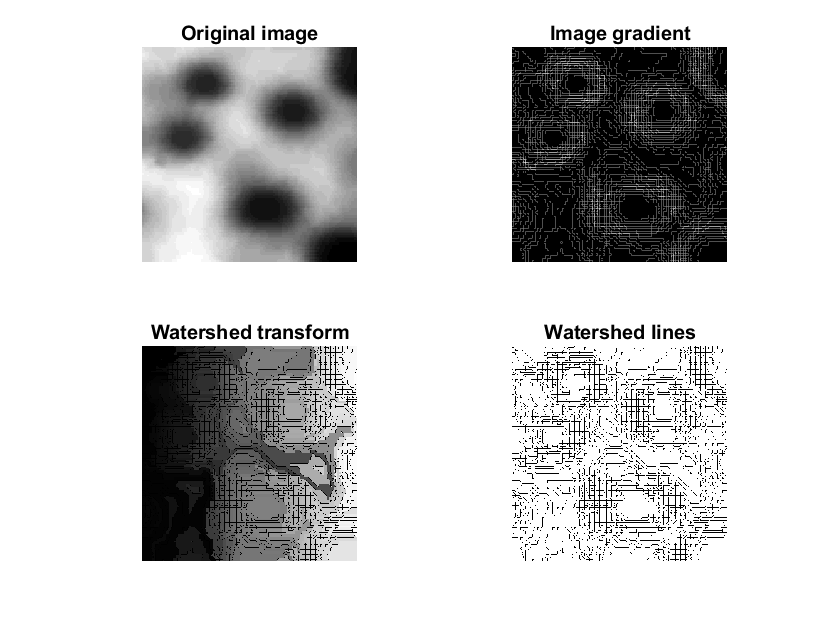

I = imread('watershed.tif');
I = double(I);
figure,subplot (2,2,1),imshow(I, []), title ("Original image");
[Grad_mag,Gdir] = imgradient(I);
subplot (2,2,2),imshow(Grad_mag, []), title ("Image gradient");
L = watershed(Grad_mag, 8);
subplot (2,2,3),imshow(L, []), title ("Watershed transform");
%L is called a label matrix, and it contains positive integers corresponding
%to the locations of each catchment basin. We can use the zero-valued elements
%of L, which are located along the watershed lines, to separate the objects in the
%original image.
wr1 = ones(size(I));
wr1(L == 0 ) = 0;
subplot (2,2,4),imshow(wr1, []), title ("Watershed lines");

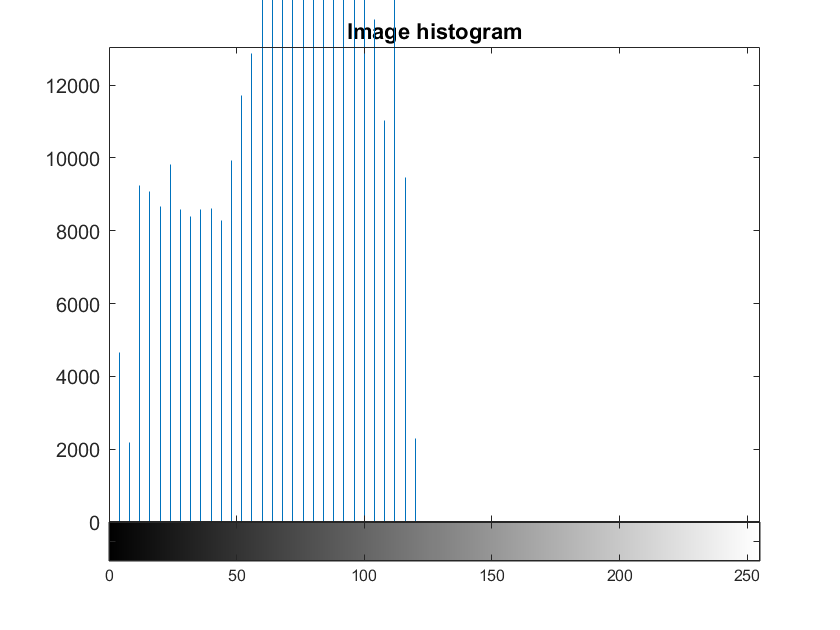


%Watershed segmentation on a binary image
I = imread('watershed.tif');
figure, imhist(I),title ("Image histogram");

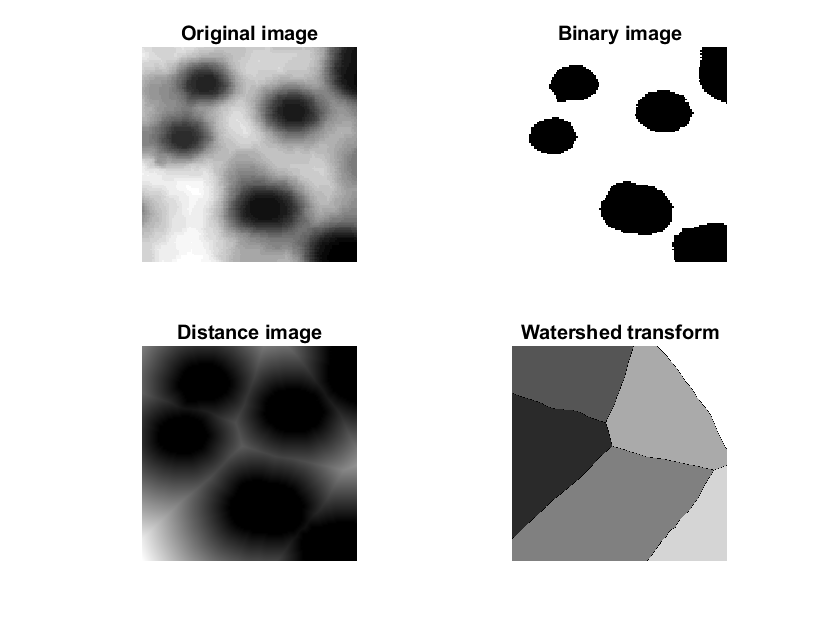

I = double(I);
figure,subplot (2,2,1),imshow(I, []), title ("Original image");
T = 50;
bw = imbinarize(I, T);
subplot (2,2,2),imshow(bw, []), title ("Binary image");
D = bwdist(~bw);
subplot (2,2,3),imshow(D, []), title ("Distance image");
L = watershed(D);
subplot (2,2,4),imshow(L, []), title ("Watershed transform");

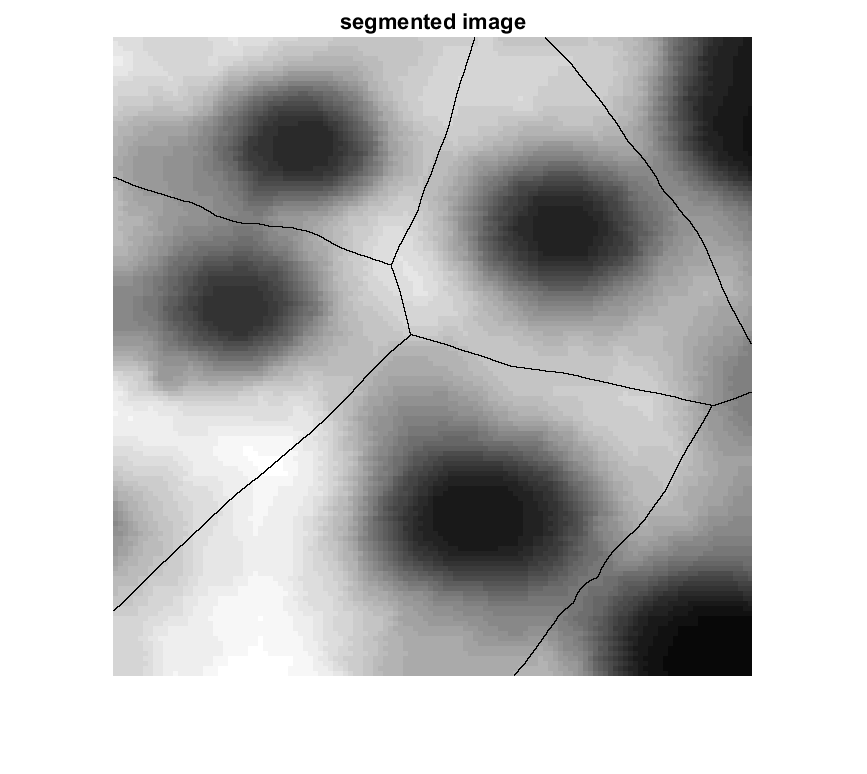

I(L == 0) = 0;
figure, imshow(I, []), title ("segmented image");

function flag = predicate(region)
    sd = std2(region);
    m = mean2(region);
    flag = (sd > 10) & (m > 0) & (m < 125); % Defines the condition
    % flag = 0.2 < max(region)- min(region) < 0.75;
end